**IMPORT DATA using datastore for large files**

fname = 'user_config.json';
fid = fopen(fname);
raw = fread(fid, inf);
str = char(raw');
fclose(fid);
config_data = jsondecode(str);
setenv("AWS_ACCESS_KEY_ID", config_data.AWS_ACCESS_KEY_ID);
setenv("AWS_SECRET_ACCESS_KEY", config_data.AWS_SECRET_ACCESS_KEY);
setenv("AWS_DEFAULT_REGION", config_data.AWS_DEFAULT_REGION);


ds = datastore("s3://prod-satia-raw-data/LOS_PROPIOS", ...
               "TextType","string",...
               "DatetimeType","datetime");

preview(ds)

ans = 8×44 table
         datetime          site_id          site_name           status     peak_power    currency    country     city             address            zip        timezone        installation_date    component_name    manufacturer          model           component_id     total_active_power    dc_voltage    power_limit_perc    total_energy    internal_temp     inverter_mode     operation_mode    ac_current_L1    ac_voltage_L1    ac_frequency_L1    apparent_power_L1    active_power_L1    reactive_p

**Examine files**

fnames = ds.Files

fnames = 68×1 cell array
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-07-05%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-07-10%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-07-15%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-07-20%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-07-25%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-07-30%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-08-04%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-08-09%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-08-14%2000:00:00_7E053322-D8.csv'}
    {'s3://prod-satia-raw-data/LOS_PROPIOS/inverter_details_2023-08-19%2000

**Read Subset of Data**

- **preview: **Read first few lines

- **read: **Read a subset of data (based on ReadSize)

- **readall: **Read all data into memory

- **tall array: **Work with all data out-of-memory

% Create a tall array to handle all data
data = tall(ds)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.

data =

  M×44 tall table

         datetime          site_id          site_name           status     peak_power    currency    country     city             address            zip        timezone        installation_date    component_name    manufacturer          model           component_id     total_active_power    dc_voltage    power_limit_perc    total_energy    internal_temp     inverter

function p = getPeakPower(data)

Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 1: Completed in 2.2 sec
Evaluation completed in 2.5 sec


peak_power = 149.6000

% Function that returns the peak power of a plant
% Inputs:
%   data: Tall array representing stored data
% Outputs:
%   p: Peak power of the plant in W

    peak_power_tab = data(1,'peak_power');
    peak_power_tab = gather(peak_power_tab);
    p = peak_power_tab.peak_power;
end
peak_power = getPeakPower(data)

**Select data of interest**

data_ts = table2timetable(data);

%Check devices and pick up the last one
devices = unique(data_ts.component_id);                 
idx = data_ts.component_id == devices(end);


% Create new features by summing them together

data_ts.total_ac_voltage = (data_ts.ac_voltage_L1 + ...
                            data_ts.ac_voltage_L2 + ...
                            data_ts.ac_voltage_L3);

data_ts.total_ac_current = (data_ts.ac_current_L1 + ...
                          data_ts.ac_current_L2 + ...
                          data_ts.ac_current_L3);

%Select features
df = unique(data_ts(idx,["total_active_power" ...

Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 2: Completed in 4.1 sec
- Pass 2 of 2: Completed in 3.5 sec
Evaluation completed in 8.4 sec


df = 46701×4 timetable
         datetime          total_active_power    dc_voltage    internal_temp    total_ac_voltage
    ___________________    __________________    __________    _____________    ________________

    2023-07-05 11:43:06              0            0.17689          26.95             708.04     
    2023-07-05 11:48:06          74982             869.25         28.301             711.86     
    2023-07-05 11:53:06              0              20.26         33.916             708.12     
    2023-07-05 11:58:06          94815             868.53         35.392             714.88     
    2023-07-05 12:03:06              0             19.461          38.58             709.26     
    2023-07-05 12:13:06  

                         "dc_voltage" ...
                         "internal_temp" ...
                         "total_ac_voltage"]));

RowTimes:

    datetime: 46701×1 datetime
        Values:
            Min         2023-07-05 11:43:06 
            Median      2024-01-06 18:03:07 
            Max         2024-06-08 13:08:08 

Variables:

    total_active_power: 46701×1 double

        Values:

            Min                0
            Median         41537
            Max       1.0037e+05

    dc_voltage: 46701×1 double

        Values:

            Min             0       
            Median          749.98  
            Max             884     
            NumMissing      41      

    internal_temp: 46701×1 double

        Values:

            Min        6.5161 
            Median      44.88 
            Max        98.725 

    total_ac_voltage: 46701×1 double

        Values:

            Min        605.66 
            Median     697.05 
            Max        731.78 





%df = df(timerange('2023-12-15 00:00:00', '2024-05-12 12:17:35'),:);

% Gather a subset of data to memory
df = gather(df)

**Explore time range and missing values**

summary(df)


d_missing =

  dictionary (cell ⟼ double) with 4 entries:

    {'total_active_power'} ⟼ 0
    {'dc_voltage'}         ⟼ 8.7793e-04
    {'internal_temp'}      ⟼ 0
    {'total_ac_voltage'}   ⟼ 0



function d = ComputeMissingPerc(df)
    varNames = df.Properties.VariableNames;
    nullPerc = zeros(1,length(varNames));
    rows = length(df.Properties.RowTimes);

    for i=1:length(varNames)
        nullPerc(i) = sum(ismissing(df(:,varNames(i)))) / rows;
    end
    d = dictionary(varNames, nullPerc);
end

d_missing = ComputeMissingPerc(df)

**Work with missing data**

- **standardizeMissing**

- **ismissing**

- **rmmissing**

- **fillmissing**

% fill missing data
function df = fillNextMissingData(df, d)
    % Function to fill missing variables using next method


d_missing =

  dictionary (cell ⟼ double) with 4 entries:

    {'total_active_power'} ⟼ 0
    {'dc_voltage'}         ⟼ 0
    {'internal_temp'}      ⟼ 0
    {'total_ac_voltage'}   ⟼ 0



    % Inputs:
    %   df: Timetable with variables to fill
    %   d: Dictionary specifying the percentage of missing values per var
    % Outputs:
    %   df_r: Timetable with filled missing data
    k = keys(d);
    v = values(d);
    for i=1:length(k)
        if v(i) > 0
            df(:, k{i}) = fillmissing(df(:,k{i}), "next");
        end
    end
end
df = fillNextMissingData(df, d_missing);
d_missing = ComputeMissingPerc(df)

**Resample to 5 mins**

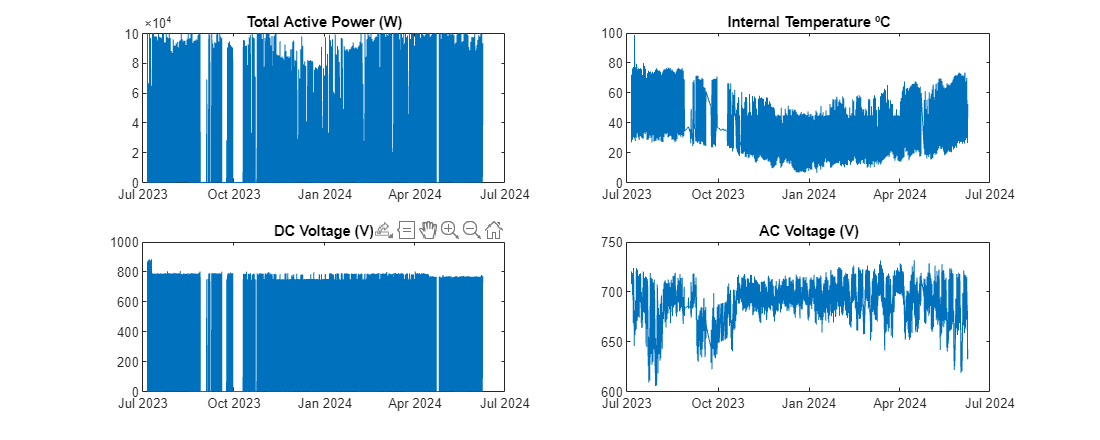

dt = minutes(5);

df_ = retime(df,'regular','median', 'TimeStep',dt);
% Fill null values with 0 except for ac_voltage
df_.total_active_power = fillmissing(df_.total_active_power, "constant", 0);
df_.dc_voltage = fillmissing(df_.dc_voltage, "constant", 0);
df_.internal_temp = fillmissing(df_.internal_temp, "linear");
df_.total_ac_voltage = fillgaps(df_.total_ac_voltage, 40, 20);

**Visualize data**

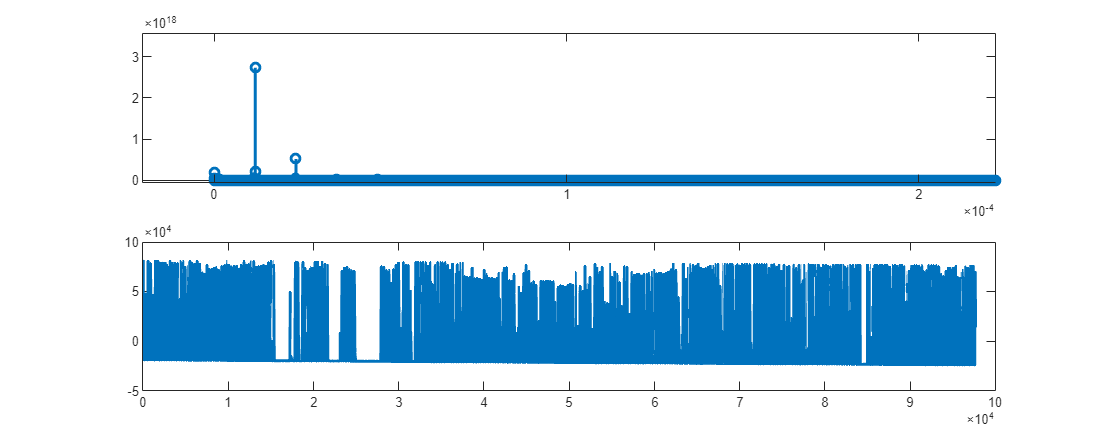

% Represent time as predictors by considering separate date components
[df_.year, df_.month, df_.day] = ymd(df_.datetime);


function visualizeFeatures(df)
% Function to visualize important variables
% Inputs:
%   df: Timetable with total_active_power, internal_temp, dc and ac voltage
    figure
    subplot(221)
    plot(df.datetime, df.total_active_power)
    title('Total Active Power (W)')
    subplot(222)
    plot(df.datetime, df.internal_temp)
    title('Internal Temperature ºC')
    subplot(223)
    plot(df.datetime, df.dc_voltage)
    title('DC Voltage (V)')
    subplot(224)
    plot(df.datetime, df.total_ac_voltage)
    title('AC Voltage (V)')
    set(gcf,'position',[10,10,1000,400])
end

visualizeFeatures(df_)

**Spectral analysis for Active Power**

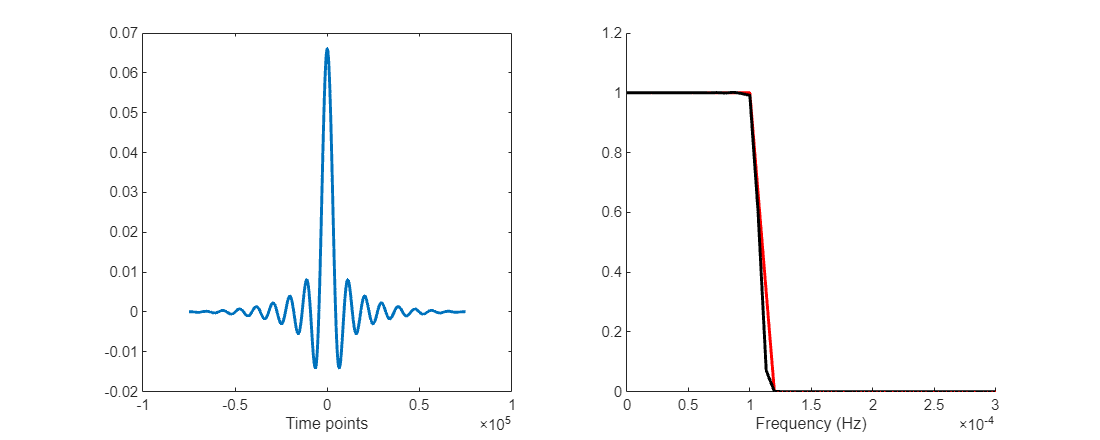

function plotFrequency(signal, sampling_rate)
    nyquist_freq = sampling_rate / 2;
    N = length(signal);
    hz = linspace(0, nyquist_freq, floor(N/2)+1);

    detsignal = detrend(signal);
    signalpow = abs(fft(detsignal)).^2;

    figure
    subplot(211)
    stem(hz,signalpow(1:length(hz)),'linew',2)
    xlim([0 .2e-3])
    subplot(212)
    plot(detsignal, "linew", 2)
    set(gcf,'position',[10,10,1000,400])
end

plotFrequency(df_.total_active_power, df_.Properties.SampleRate)

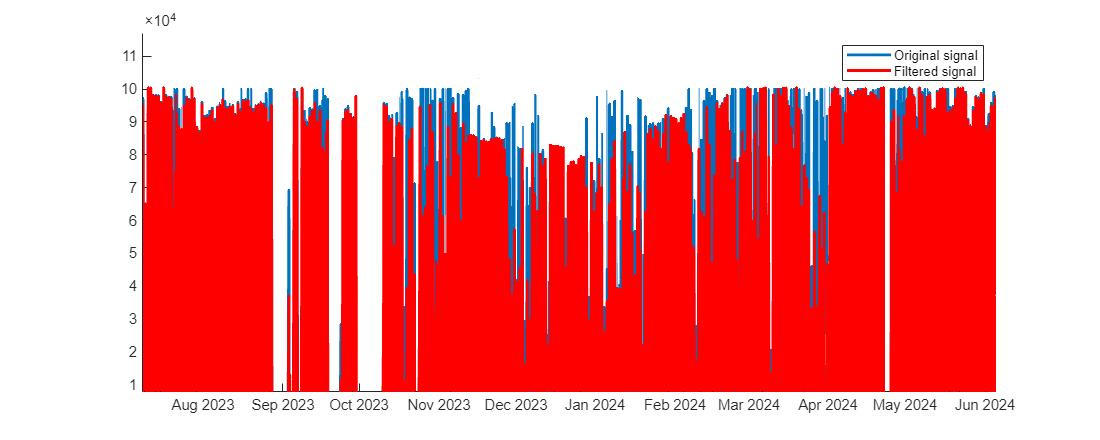


% Design a lowerband filter
function kernel =  CreateLowerBandFilter(df, fcuttoff, filtorder)

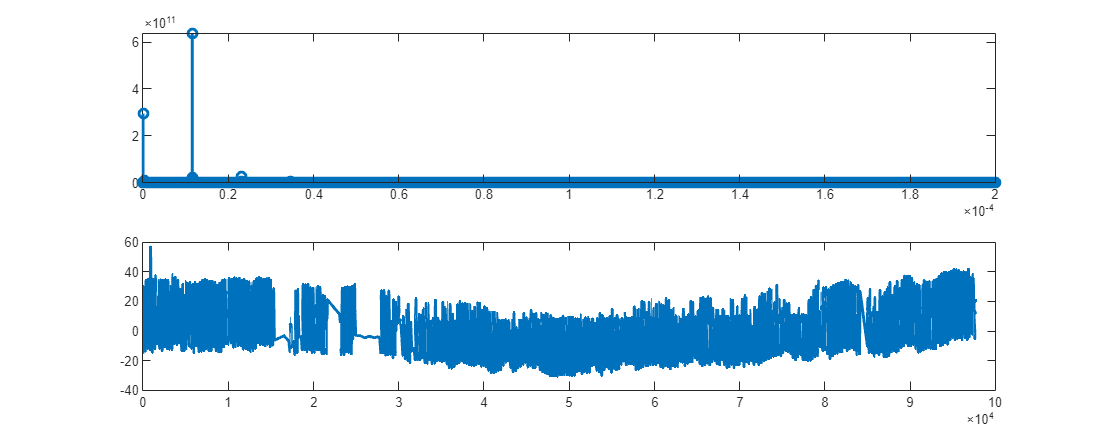

    fs = df.Properties.SampleRate;
    nyquist_freq = fs / 2;
    transw = .2;

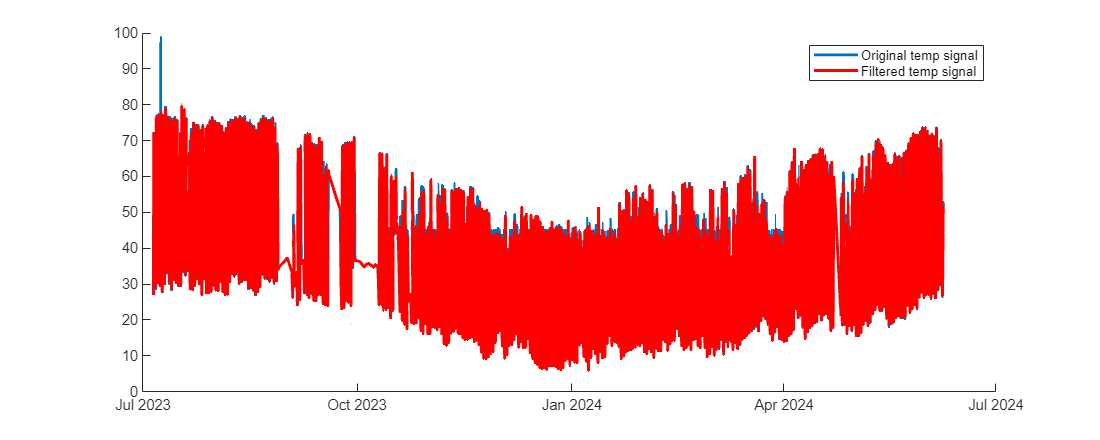

    filter_shape = [1 1 0 0];
    frex = [0 fcuttoff fcuttoff*(1+transw) nyquist_freq] / nyquist_freq;
    kernel = firls(filtorder, frex, filter_shape);

    % Define frequency range
    hz = linspace(0, fs/2, floor(length(kernel)/2)+1);
    filpw = abs(fft(kernel)).^2;

    figure

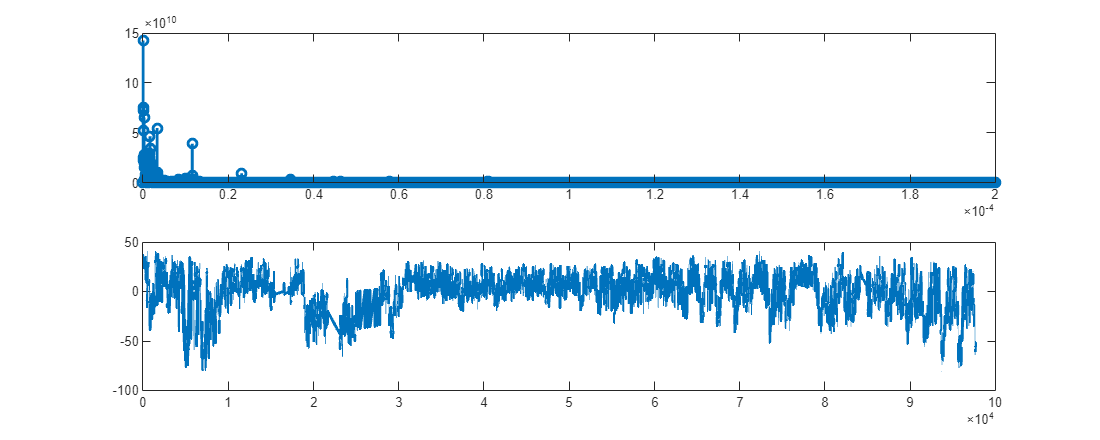

    subplot(121)
    plot((-filtorder/2:filtorder/2)/fs, kernel,'linew',2)
    xlabel('Time points')

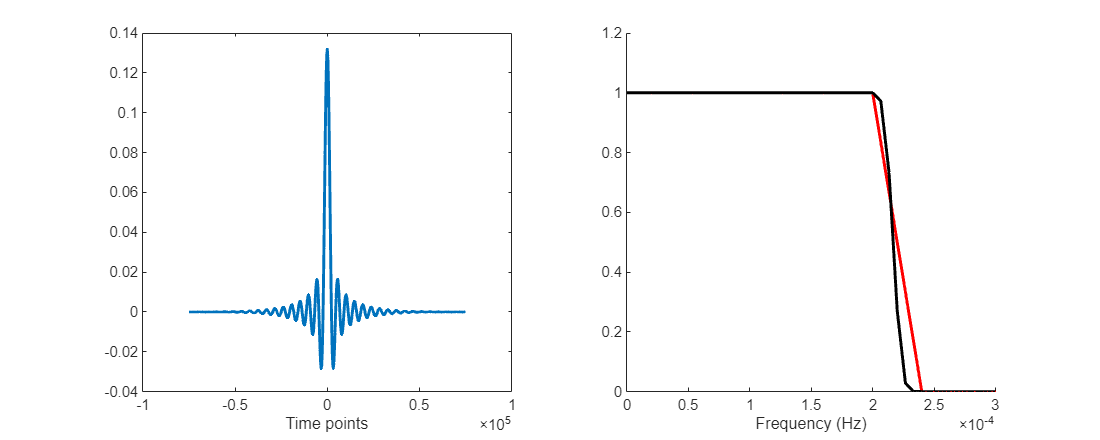

    subplot(122)
    hold on
    plot(frex*nyquist_freq, filter_shape, 'r', 'linew',2)
    plot(hz,filpw(1:length(hz)),'k','linew',2)
    xlabel('Frequency (Hz)')
    set(gca,'xlim',[0 3e-4])

    set(gcf,'position',[10,10,1000,400])
end
% Define filter parameters

fc = 1e-4;
order = 500;

filterkern = CreateLowerBandFilter(df_, fc, order);

**Apply the filter to power signal**

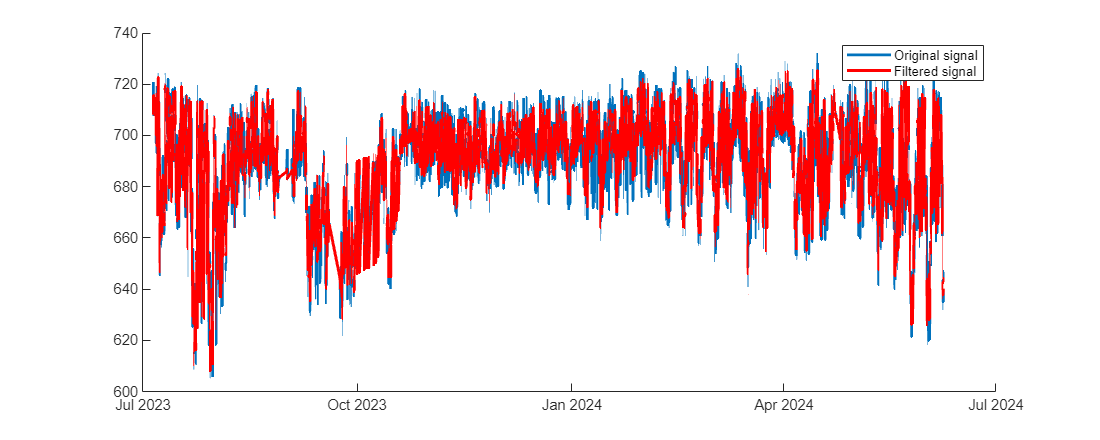

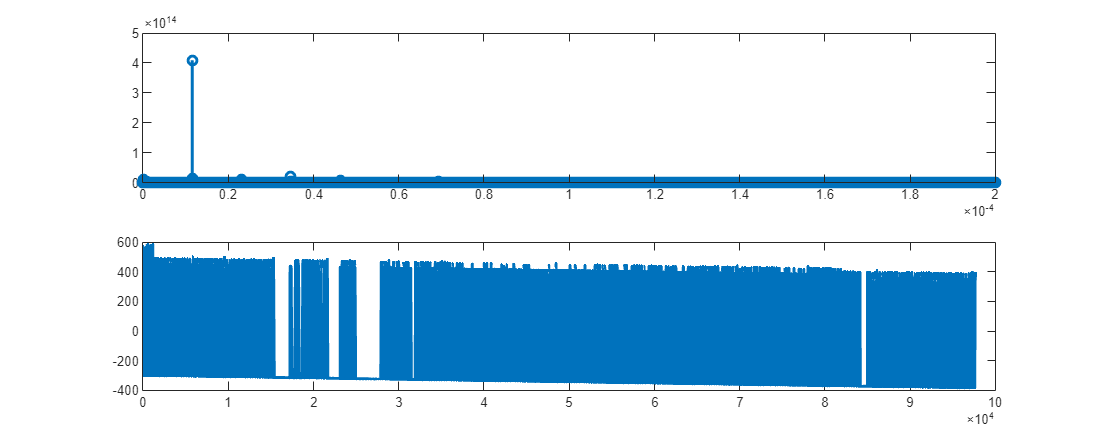

df_.filtered_power = filtfilt(filterkern, 1, df_.total_active_power);
idx_min = (df_.filtered_power < 0.5e4);

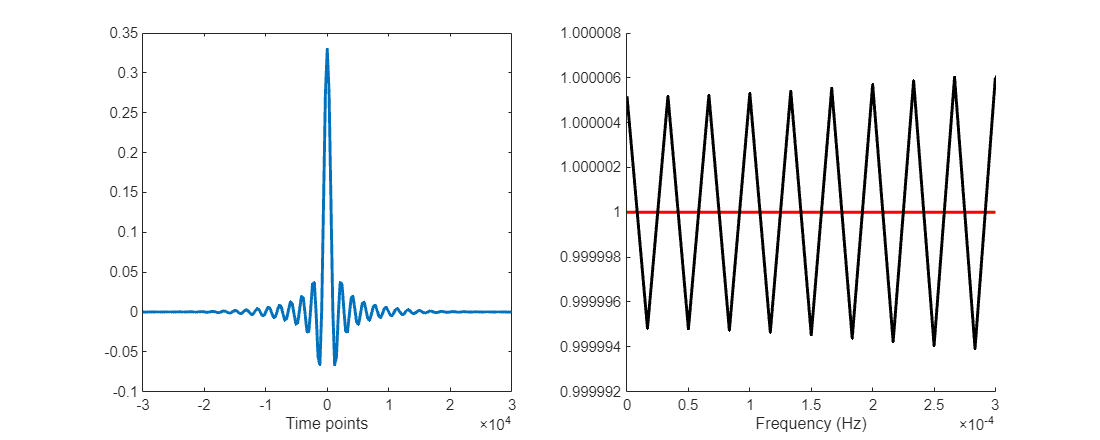

idx_max = (df_.filtered_power >= max(df_.total_active_power));
df_.filtered_power(idx_min) = 0;
df_.filtered_power(idx_max) = max(df_.total_active_power);


figure

hold on
plot(df_.datetime, df_.total_active_power, 'linew', 2)
plot(df_.datetime, df_.filtered_power, 'r', 'linew', 2)
legend('Original signal', 'Filtered signal')
set(gcf,'position',[10,10,1000,400])

**Spectral Analysis Internal Temperature**

plotFrequency(df_.internal_temp, df_.Properties.SampleRate)

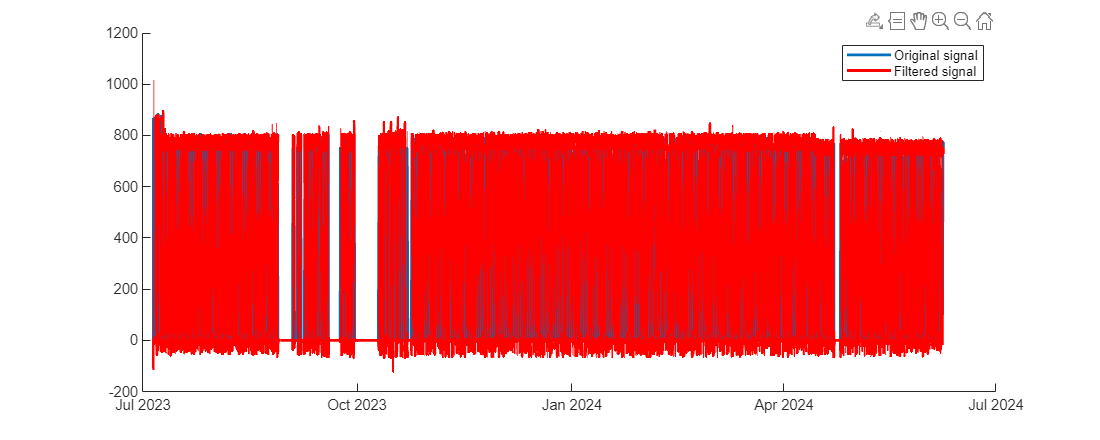

df_.filtered_temp = filtfilt(filterkern, 1, df_.internal_temp);

figure

hold on
plot(df_.datetime, df_.internal_temp, 'linew', 2)
plot(df_.datetime, df_.filtered_temp, 'r', 'linew', 2)
legend('Original temp signal', 'Filtered temp signal')
set(gcf,'position',[10,10,1000,400])

df_ = 42983×16 timetable
         datetime          total_active_power    dc_voltage    internal_temp    total_ac_voltage    year    day    filtered_power    filtered_temp    filtered_ac    filtered_dc    April    December    February    January    March    May
    ___________________    __________________    __________    _____________    ________________    ____    ___    ______________    _____________    ___________    ___________    _____    ________    ________  

**Spectral Analysis AC Voltage**

plotFrequency(df_.total_ac_voltage, df_.Properties.SampleRate)

% Create a lowpass band filter for AC voltage
fc = 2e-4;
order = 500;

filterkern = CreateLowerBandFilter(df_, fc, order);

df_.filtered_ac = filtfilt(filterkern, 1, df_.total_ac_voltage);

figure
hold on
plot(df_.datetime, df_.total_ac_voltage, 'linew', 2)
plot(df_.datetime, df_.filtered_ac, 'r', 'linew', 2)
legend('Original signal', 'Filtered signal')
set(gcf,'position',[10,10,1000,400])

plotFrequency(df_.dc_voltage, df_.Properties.SampleRate)

% Create low pass band filter for DC voltage
fc = 5e-4;
order = 200;

filterkern = CreateLowerBandFilter(df_, fc, order);

df_.filtered_dc = filtfilt(filterkern, 1, df_.dc_voltage);

figure
hold on
plot(df_.datetime, df_.dc_voltage, 'linew', 2)
plot(df_.datetime, df_.filtered_dc, 'r', 'linew', 2)
legend('Original signal', 'Filtered signal')
set(gcf,'position',[10,10,1000,400])

**One-Hot encoding Categorical Features**

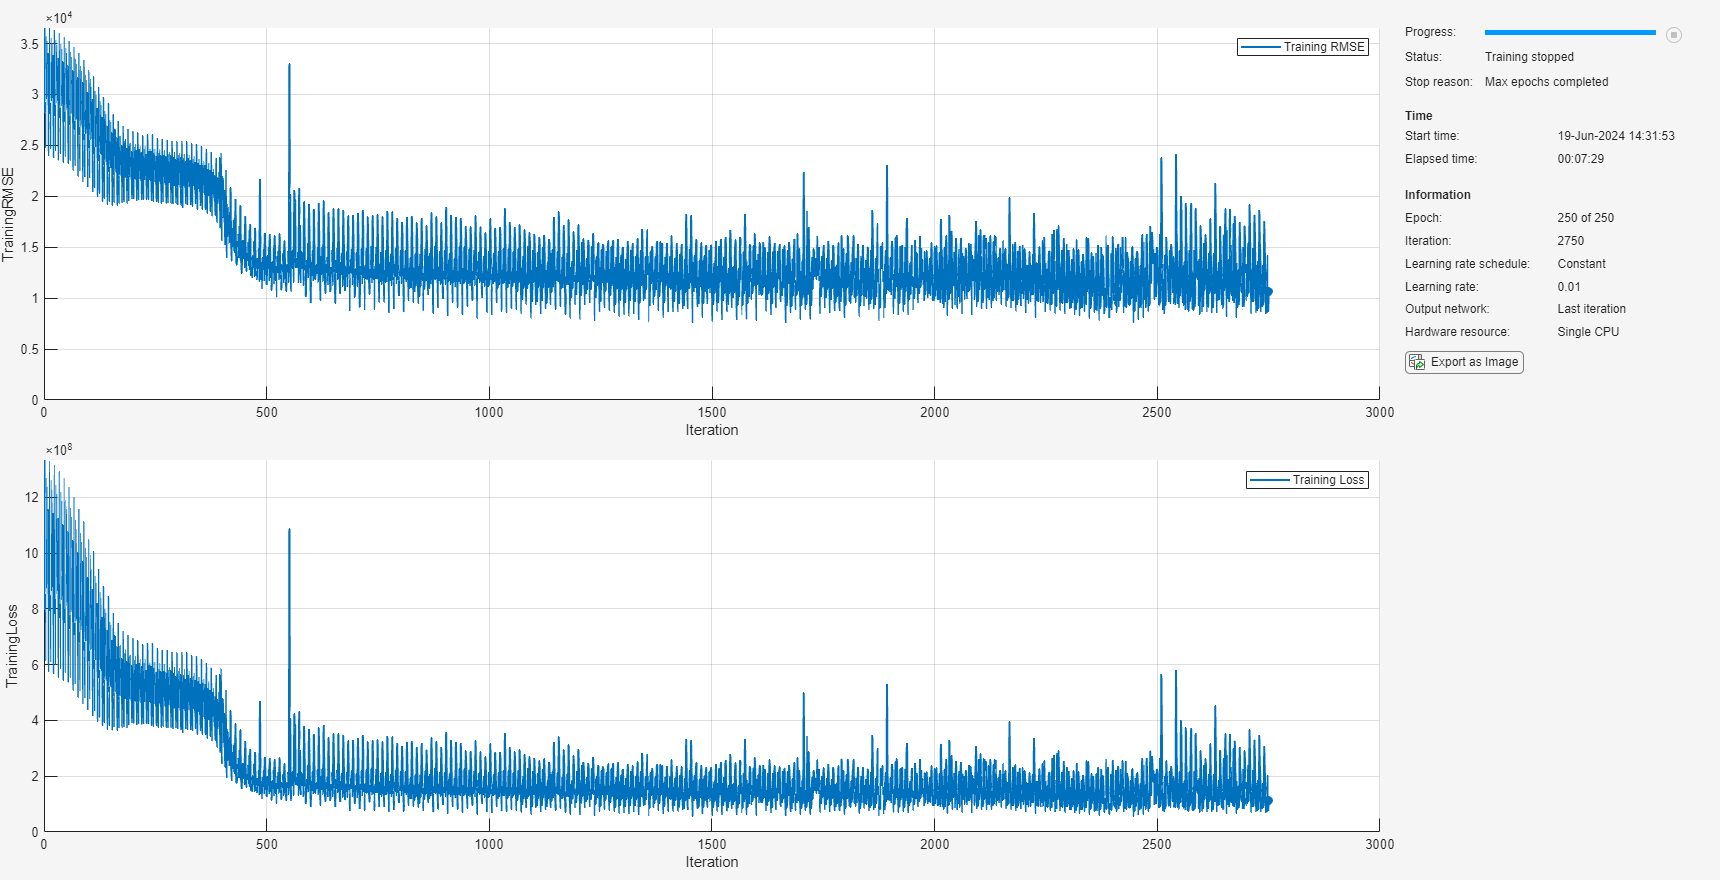

df_.month = datestr(datetime(1, df_.month, 1), 'mmmm');

df_ = [df_ onehotencode(table(categorical(cellstr(df_.month))))];
df_ = removevars(df_, 'month')

**Create a neural network to predict power**

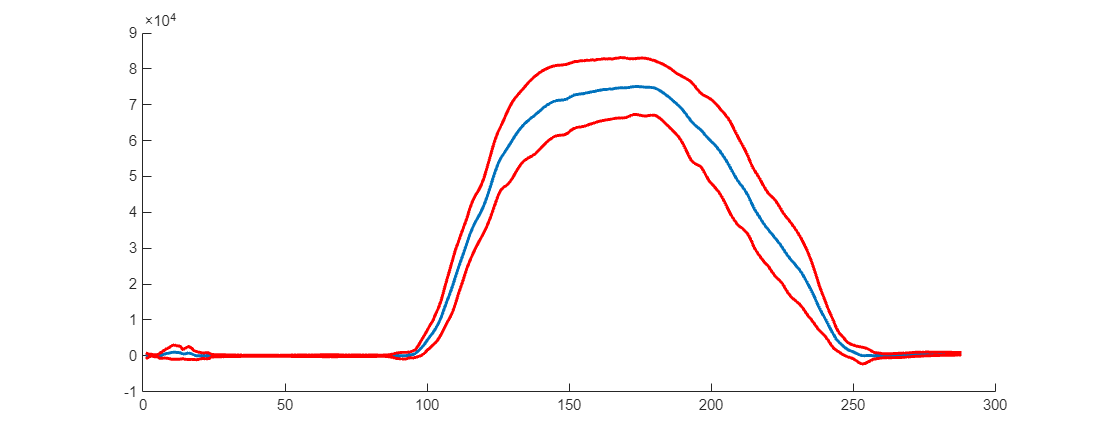

% Prepare dataset

function [X, Y] = prepareDataSet(df_)
    startDate = min(df_.datetime);
    endDate = max(df_.datetime);
    endSeqDate = startDate + days(1);
    X = {};
    Y = {};
    if (hour(endSeqDate) ~= 0) || (minute(endSeqDate) ~= 0)
        endSeqDate.Hour = 0;
        endSeqDate.Minute = 0;

    end
    
    while (endSeqDate + days(1)) <= endDate
        Xidx = timerange(startDate, endSeqDate);
        Yidx = timerange(endSeqDate, endSeqDate + days(1));
        X_tmp = removevars(timetable2table(df_(Xidx,:)), ...
                      {'datetime', ...
                       'total_active_power', ...
                       'dc_voltage', ...
                       'internal_temp', ...
                       'total_ac_voltage', ...
                       'year', ...
                       'day'});
        Y_tmp = timetable2table(df_(Yidx,:));
        Y_tmp = Y_tmp(:, "filtered_power");
    
        X = [X; table2array(X_tmp)];
        Y = [Y; table2array(Y_tmp)];
        startDate = endSeqDate;
        endSeqDate = startDate + days(1);
    end
end

[X, Y] = prepareDataSet(df_);

% Divide data between train and test
idxTrain = 1:floor(0.8*numel(X));
idxTest = floor(0.8*numel(X))+1:numel(X);

Xtrain = X(idxTrain);
Ytrain = Y(idxTrain);

Xtest = X(idxTest);
Ytest = Y(idxTest);

% Define LTSM arquitecture
numChannels = size(Xtrain{1}, 2);
numResponses = size(Ytrain{1}, 2);
numHiddenUnits = 200;

layers = [...
          sequenceInputLayer(numChannels, Normalization="zscore")
          lstmLayer(numHiddenUnits, OutputMode="sequence")
          fullyConnectedLayer(50)
          dropoutLayer(0.2)
          fullyConnectedLayer(numResponses)];

% Define options of the layer
maxEpochs = 250;
miniBatchSize = 10;

options = trainingOptions("adam", ...
    MaxEpochs=maxEpochs, ...
    MiniBatchSize= miniBatchSize, ...
    InitialLearnRate=0.01, ...
    GradientThreshold=1, ...
    Shuffle="never", ...
    Metrics="rmse", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainnet(Xtrain, Ytrain, layers, "mse", options);

% Evaluate Predictions
scores = minibatchpredict(net, Xtest);

predictions_mean = mean(scores, 3);
predictions_mean(predictions_mean < 0) = 0;
predictions_std = std(scores, 0, 3);
figure
hold on
plot(predictions_mean, 'linew', 2)
plot(predictions_mean + predictions_std, 'r', 'linew', 2)
plot(predictions_mean - predictions_std, 'r', 'linew', 2)
set(gcf,'position',[10,10,1000,400])